# RVC2: Chapter 15 - Visual Servoing

format compact
close all
clear
clc

## 15.1  Position-based visual servoing

cam = CentralCamera('default');

principal point not specified, setting it to centre of image plane


creating new figure for camera


h =   Axes with properties:

             XLim: [0 1024]
             YLim: [0 1024]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties

make axes


p =   445.3333  445.3333  578.6667  578.6667
  445.3333  578.6667  578.6667  445.3333

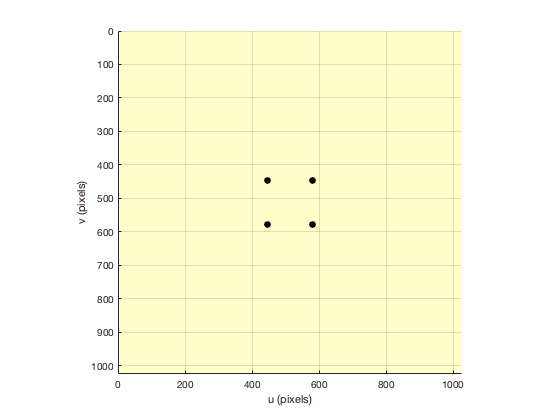


P = mkgrid( 2, 0.5, 'pose', SE3(0,0,3) );

T_C = SE3(0,0,0);  %DIFF
Cd_T_G = SE3(0.1, 0.2, 0.5); %DIFF
p = cam.plot(P, 'pose', T_C)


C_Te_G = cam.estpose(P, p);

T_delta = C_Te_G * inv(Cd_T_G);

lambda = 0.2;  %DIFF
T_C = T_C .* T_delta.interp(lambda);

T_C0 = SE3(1,1,-3)*SE3.Rz(0.6);

Cd_T_G = SE3(0, 0, 1);

pbvs = PBVS(cam, 'pose0', T_C0, 'posef', Cd_T_G, 'axis', [-1 2 -1 2 -3 0.5])

pbvs = 
Visual servo object: camera=default
  200 iterations, 0 history
  P= -0.25       -0.25        0.25        0.25                 
     -0.25        0.25        0.25       -0.25                 
         0           0           0           0                 
  C_T0:   t = ( 1,  1,  -3), R = ( 34.3775deg |  0,  0,  1)    
  C*_T_G: t = ( 0,  0,  1), R = ( 0deg |  0,  0,  0)           


completed on iteration count


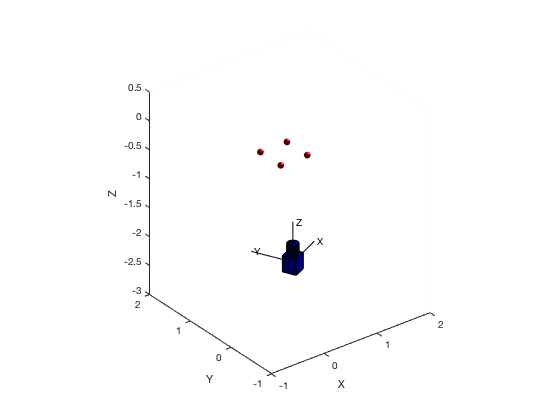

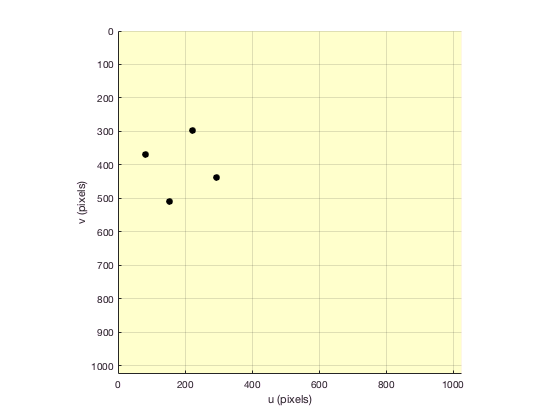


pbvs.run(5);

ans =    80.5819  368.4916  150.8874  508.8845  291.2804  438.5790  220.9749  298.1861

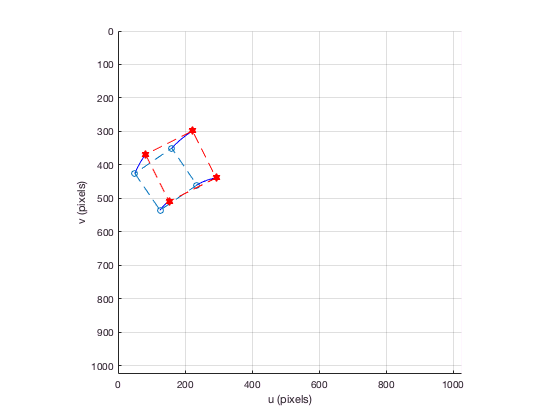


pbvs.plot_p();

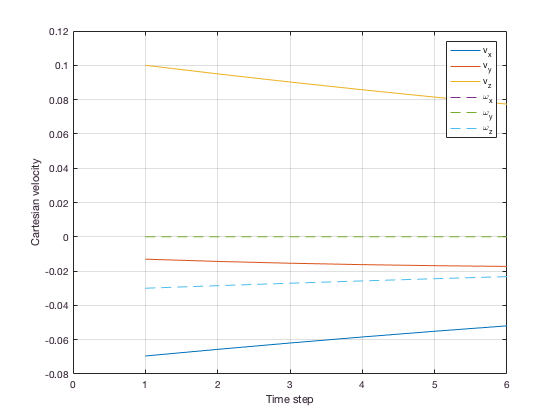

pbvs.plot_vel();

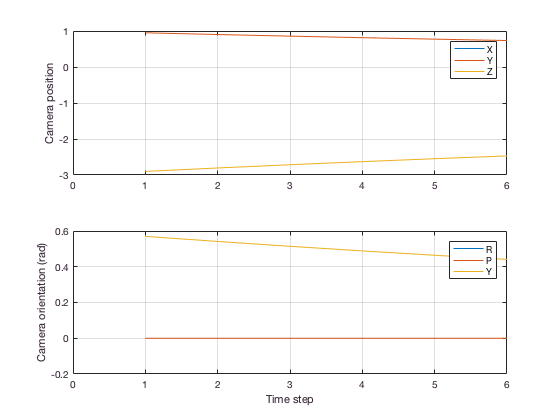

pbvs.plot_camera();

## 15.2  Image-based visual servoing

## 15.2.1  Camera and image motion

cam = CentralCamera('default');

principal point not specified, setting it to centre of image plane



P = [1 1 5]';

p0 = cam.project( P )

p0 =    672
   672


px = cam.project( P, 'pose', SE3(0.1,0,0) )

px =    656
   672


( px - p0 ) / 0.1

ans =   -160
     0


( cam.project( P, 'pose', transl(0, 0, 0.1) ) - p0 ) / 0.1

ans =    32.6531
   32.6531


( cam.project( P, 'pose', trotx(0.1) ) - p0 ) / 0.1

ans =    40.9626
  851.8791


J = cam.visjac_p([672; 672], 5)

J =  -160.0000         0   32.0000   32.0000 -832.0000  160.0000
         0 -160.0000   32.0000  832.0000  -32.0000 -160.0000

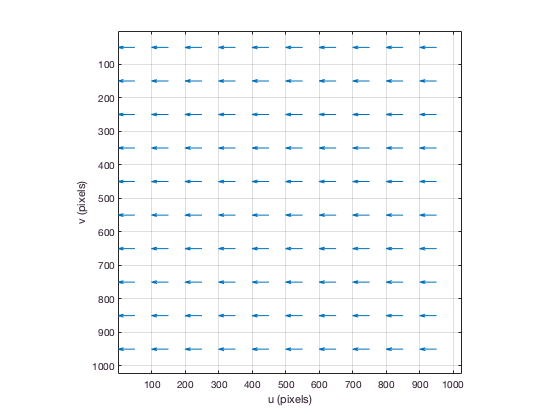



clf
cam.flowfield( [1 0 0 0 0 0] );

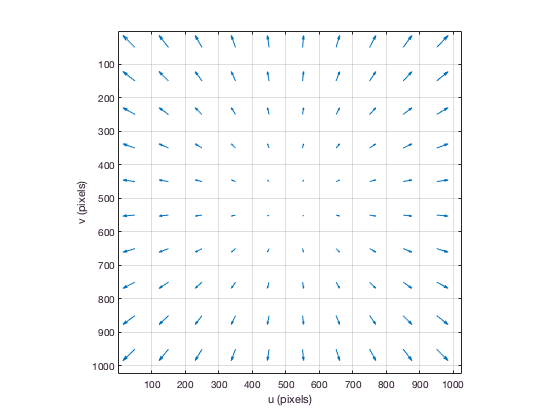


cam.flowfield( [0 0 1 0 0 0] );

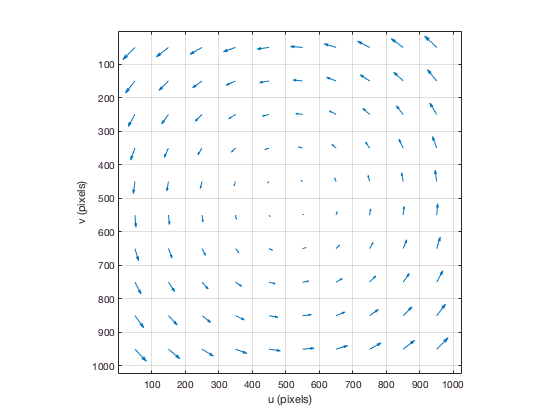


cam.flowfield( [0 0 0 0 0 1] );

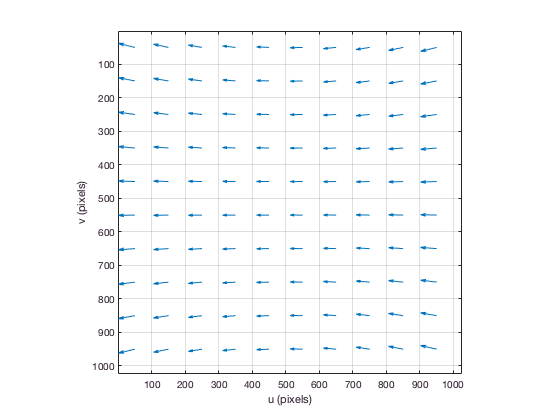


cam.flowfield( [0 0 0 0 1 0] );


cam.visjac_p(cam.pp', 1)

ans =  -800.0000         0         0         0 -800.0000         0
         0 -800.0000         0  800.0000         0         0

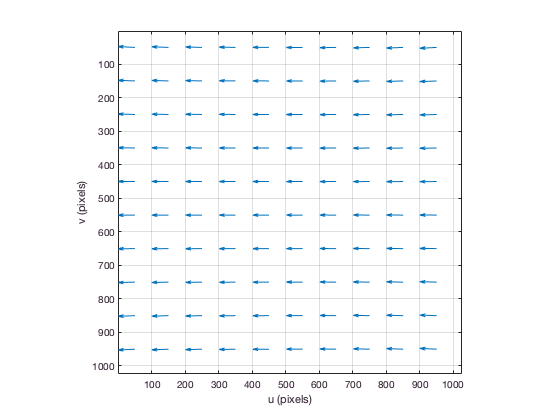


cam.f = 20e-3;
cam.flowfield( [0 0 0 0 1 0] );

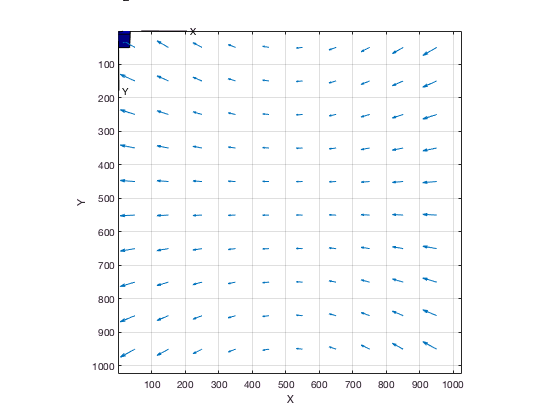


cam.f = 4e-3;
cam.flowfield( [0 0 0 0 1 0] );


J = cam.visjac_p(cam.pp', 1);
null(J)

ans =          0         0   -0.7071         0
         0    0.7071         0         0
    1.0000         0         0         0
         0    0.7071         0         0
         0         0    0.7071         0
         0         0         0    1.0000

## 15.2.2  Controlling feature motion

cam = CentralCamera('default');

principal point not specified, setting it to centre of image plane


creating new figure for camera


h =   Axes with properties:

             XLim: [0 1024]
             YLim: [0 1024]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties

make axes


p =   445.3333  445.3333  578.6667  578.6667
  445.3333  578.6667  578.6667  445.3333


P = mkgrid( 2, 0.5, 'pose', SE3(0,0,3) );

pd = bsxfun(@plus, 200*[-1 -1 1 1; -1 1 1 -1], cam.pp');

T_C = SE3(0,0,0); %DIFF
%transl(1,1,-3)*trotz(0.6)

p = cam.plot(P, 'pose', T_C)


e = pd - p;

J = cam.visjac_p(p, 1);

v = lambda * pinv(J) * e(:);

T_C = T_C .* SE3.delta(v);

T_C0 = SE3(1,1,-3)*SE3.Rx(0.6)


T_C0 = 
         1         0         0         1
         0    0.8253   -0.5646         1
         0    0.5646    0.8253        -3
         0         0         0         1



ibvs = IBVS(cam, 'pose0', T_C0, 'pstar', pd)

ibvs = 
Visual servo object: camera=default
   iterations, 0 history
  P= -0.25       -0.25        0.25        0.25              
     -0.25        0.25        0.25       -0.25              
         0           0           0           0              
  C_T0:   t = ( 1,  1,  -3), R = ( 34.3775deg |  1,  0,  0) 


completed on error tolerance


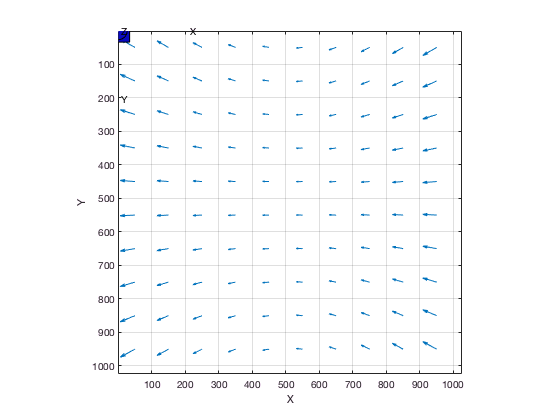


ibvs.run();

ans =   311.9387  312.2290  311.9205  712.0855  711.7881  712.0923  711.7838  312.2360

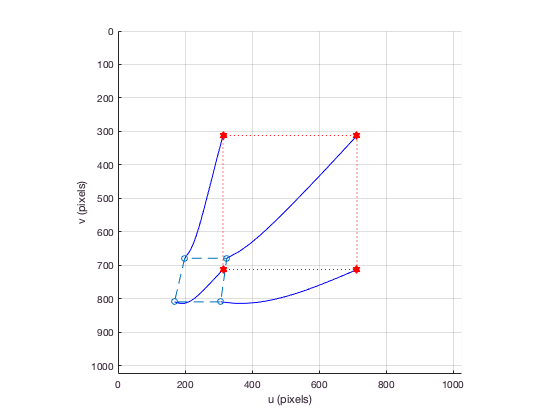


ibvs.plot_p();

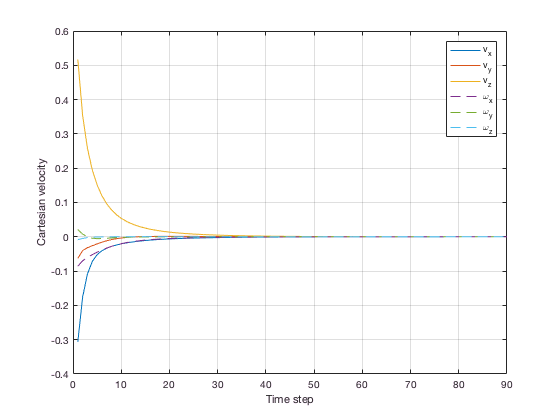

ibvs.plot_vel();

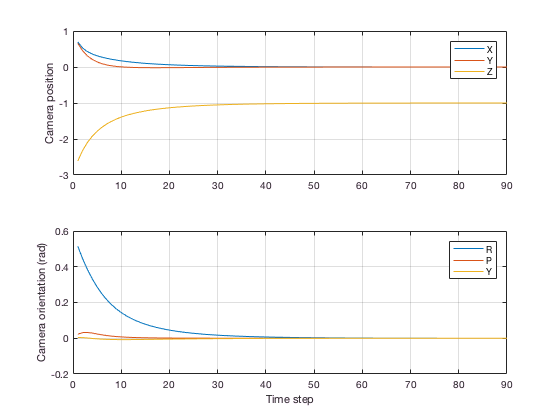

ibvs.plot_camera();

sl_ibvs

principal point not specified, setting it to centre of image plane
camera = 
name: default [central-perspective]                     
  focal length:   0.008                                 
  pixel size:     (1e-05, 1e-05)                        
  principal pt:   (512, 512)                            
  number pixels:  1024 x 1024                           
  T:              t = (0, 0, 0), RPY/zyx = (0, 0, 0) deg
creating new figure for camera


h =   Axes with properties:

             XLim: [0 1024]
             YLim: [0 1024]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties

make axes



Simulink.SimulationOutput:

    tout: [501×1 double]
    yout: [1×1 struct]
Use get to access a variable by name.
Use getSimulationMetadata to access metadata about the simulation.



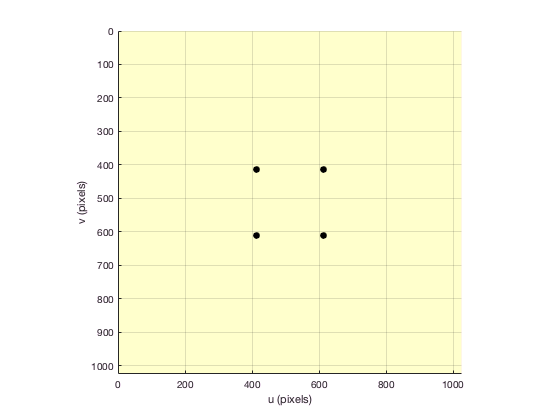


r = sim('sl_ibvs')


t = r.find('tout');
v = r.find('yout').signals(2).values;
about(v)

v [double] : 501x6 (24.0 kB)


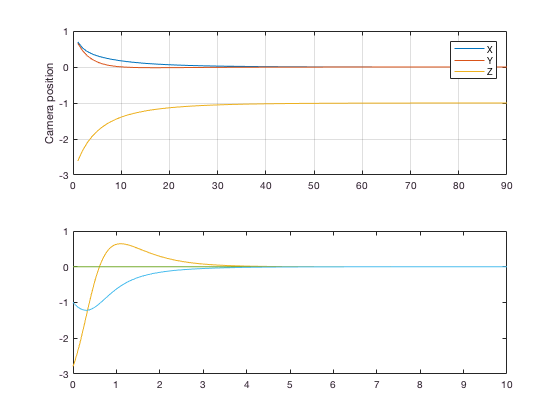


plot(t, v)


p = r.find('yout').signals(1).values;
about(p)

p [double] : 2x4x501 (32.1 kB)


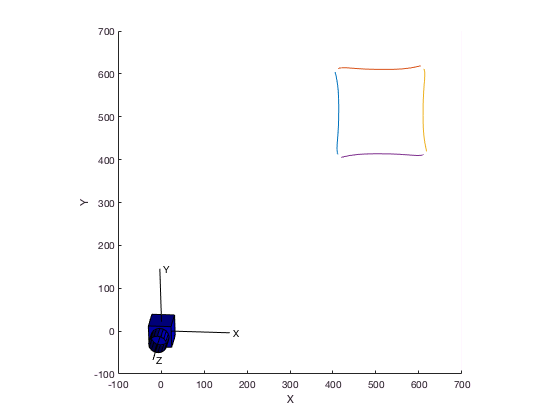

plot2(p)

## 15.2.3  Estimating feature depth

ibvs = IBVS(cam, 'pose0', T_C0, 'pstar', pd, 'depth', 1)

ibvs = 
Visual servo object: camera=default
   iterations, 0 history
  P= -0.25       -0.25        0.25        0.25              
     -0.25        0.25        0.25       -0.25              
         0           0           0           0              
  C_T0:   t = ( 1,  1,  -3), R = ( 34.3775deg |  1,  0,  0) 


completed on iteration count


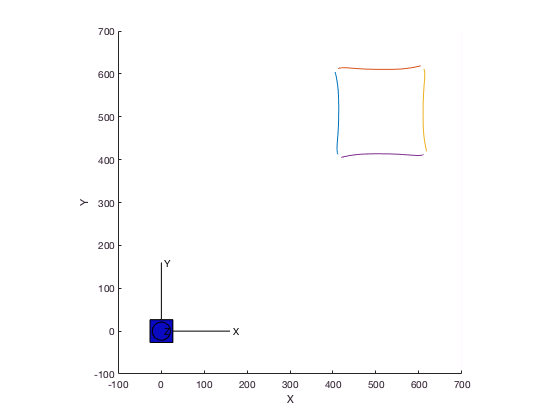

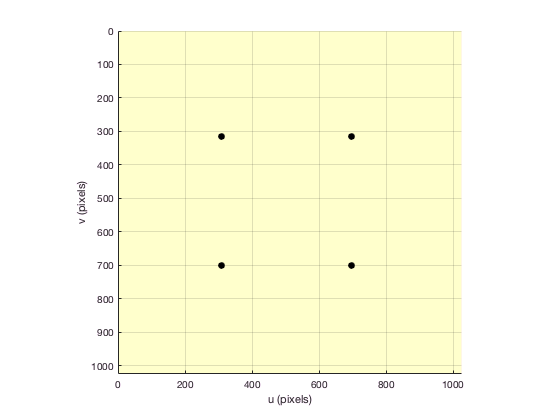

ibvs.run(50)



ibvs.plot_p(); % DIFF

ans =   306.6093  313.6954  306.5024  701.2699  694.1796  701.3949  694.2031  313.6926

ibvs = IBVS(cam, 'pose0', T_C0, 'pstar', pd, 'depth', 10)

ibvs = 
Visual servo object: camera=default
   iterations, 0 history
  P= -0.25       -0.25        0.25        0.25              
     -0.25        0.25        0.25       -0.25              
         0           0           0           0              
  C_T0:   t = ( 1,  1,  -3), R = ( 34.3775deg |  1,  0,  0) 


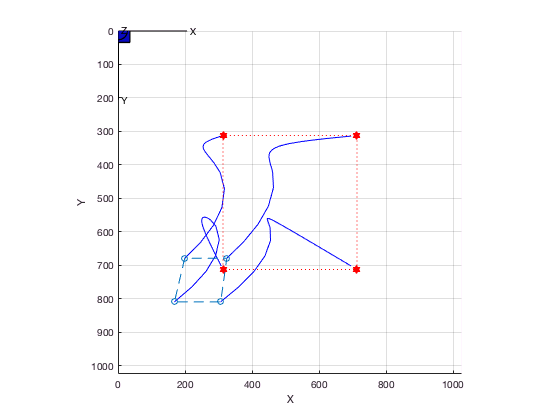

completed on iteration count


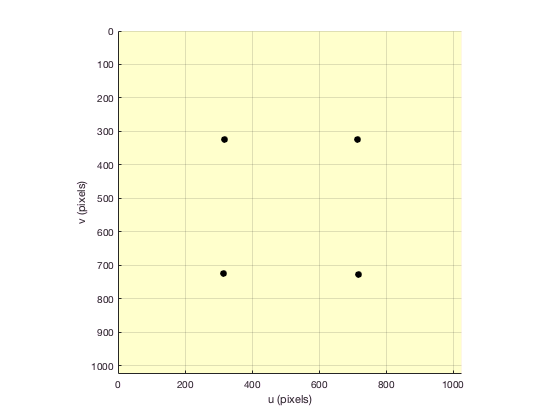

ibvs.run(50)

ibvs.plot_p(); % DIFF

ans =   316.0393  325.3145  314.5234  725.1270  716.2468  725.5120  714.6449  324.9051


ibvs = IBVS(cam, 'pose0', T_C0, 'pstar', pd, 'depthest')

ibvs = 
Visual servo object: camera=default
   iterations, 0 history
  P= -0.25       -0.25        0.25        0.25              
     -0.25        0.25        0.25       -0.25              
         0           0           0           0              
  C_T0:   t = ( 1,  1,  -3), R = ( 34.3775deg |  1,  0,  0) 


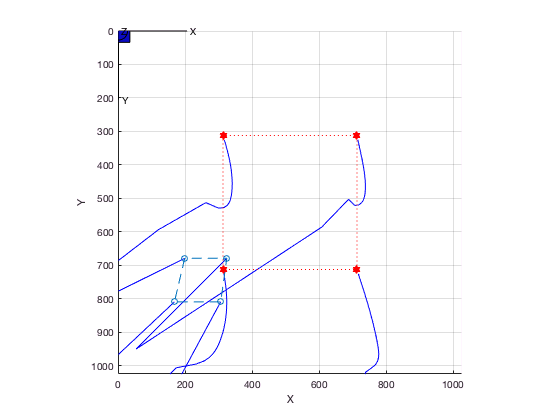

completed on error tolerance


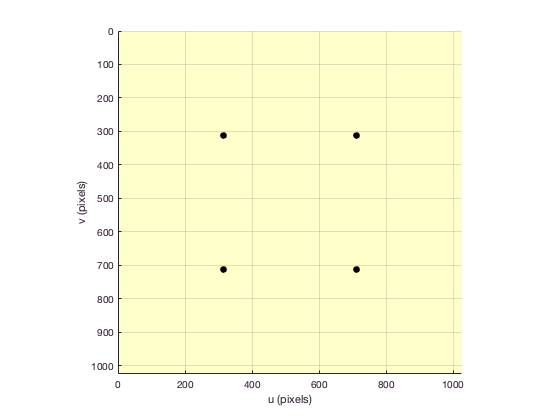

ibvs.run()

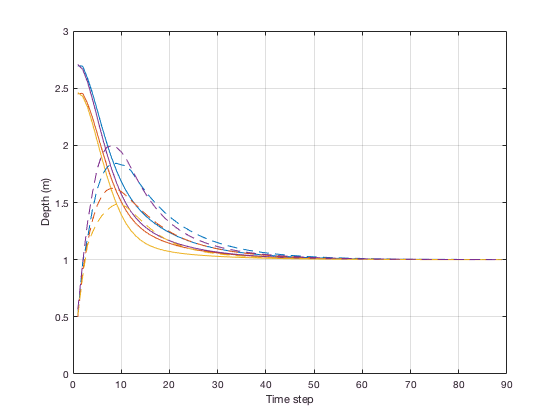

ibvs.plot_z()

ans =   312.1030  312.2999  312.0405  712.0906  711.9135  712.1463  711.8869  312.2801

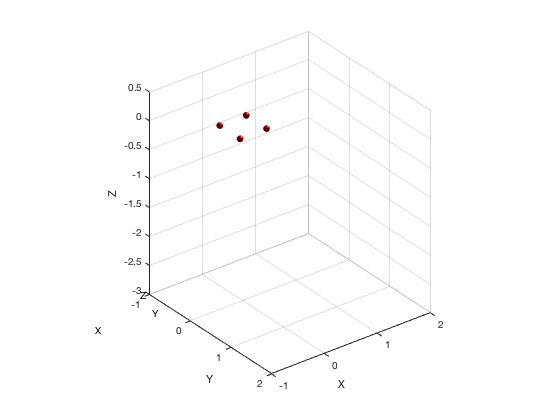

ibvs.plot_p()

## 15.2.4  Performance issues

completed on iteration count


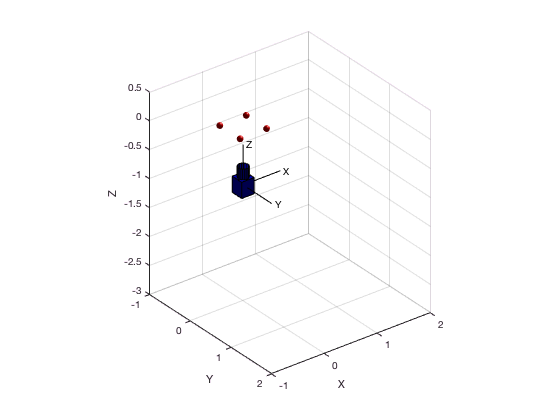

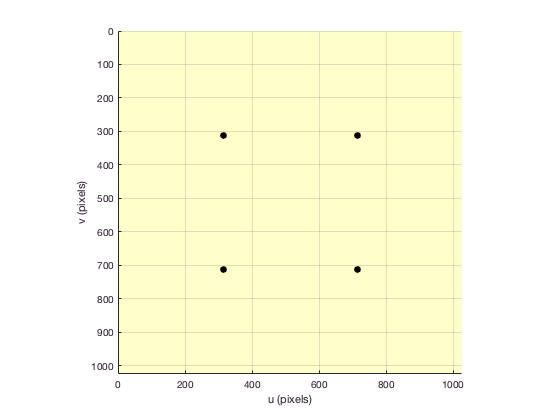

pbvs.T0 = SE3(-2.1, 0, -3)*SE3.Rz(5*pi/4);
pbvs.run()

ibvs.plot_p();

ans =   312.1030  312.2999  312.0405  712.0906  711.9135  712.1463  711.8869  312.2801


ibvs = IBVS(cam, 'pose0', pbvs.T0, 'pstar', pd, 'lambda', 0.002, 'niter', Inf, 'eterm', 0.5)

ibvs = 
Visual servo object: camera=default
  Inf iterations, 0 history
  P= -0.25       -0.25        0.25        0.25                 
     -0.25        0.25        0.25       -0.25                 
         0           0           0           0                 
  C_T0:   t = ( -2.1,  0,  -3), R = ( 135deg |  0,  0,  -1)    


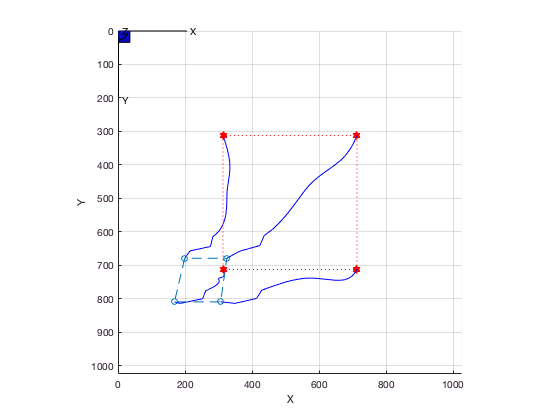

completed on error tolerance


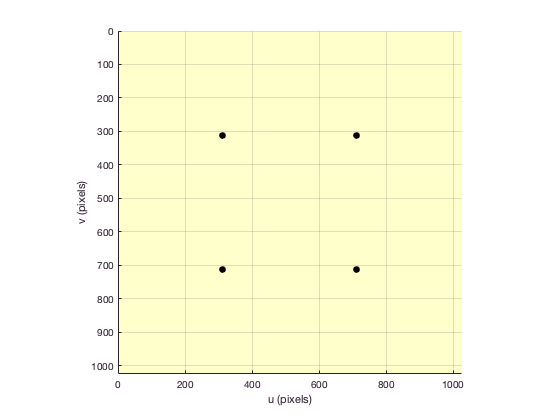

ibvs.run()

ibvs.plot_p();

ans =   311.9600  312.2238  311.9250  712.0387  711.7398  712.0737  711.7748  312.2588

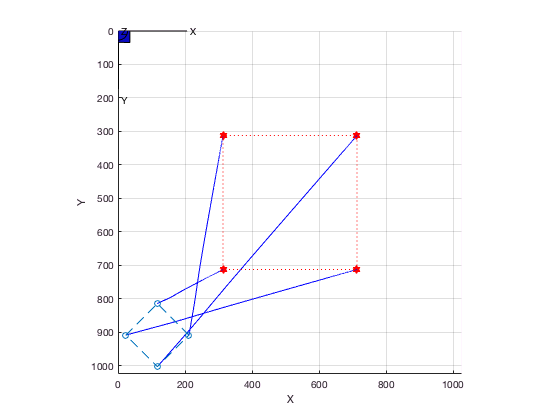

completed on error tolerance


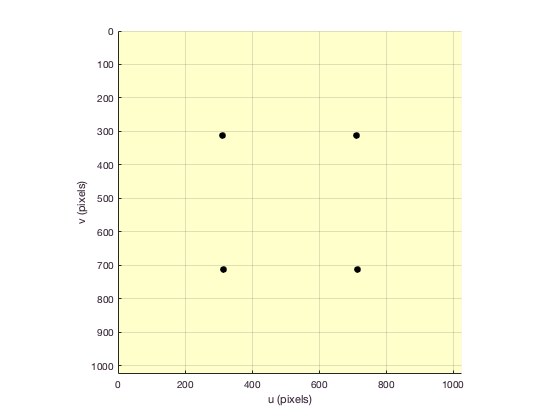


ibvs = IBVS(cam, 'pose0', SE3(0,0, -1)*SE3.Rz(1), 'pstar', pd);
ibvs.run()

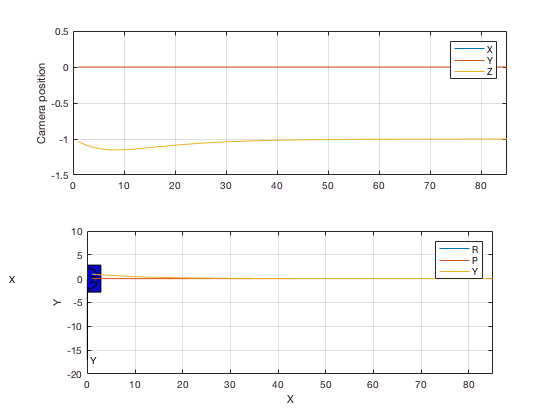

completed on iteration count


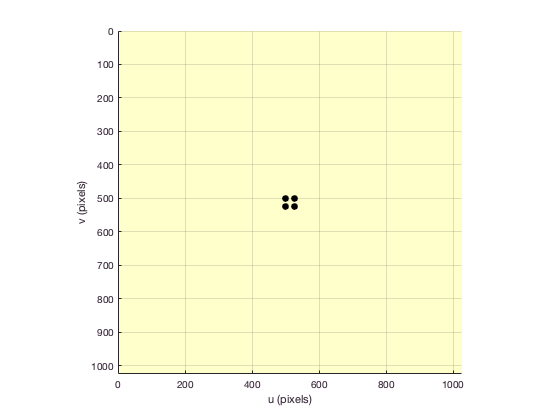

ibvs.plot_camera

ibvs = IBVS(cam, 'pose0',  transl(0,0, -1)*trotz(pi), ...
    'pstar', pd, 'niter', 10);
ibvs.run()

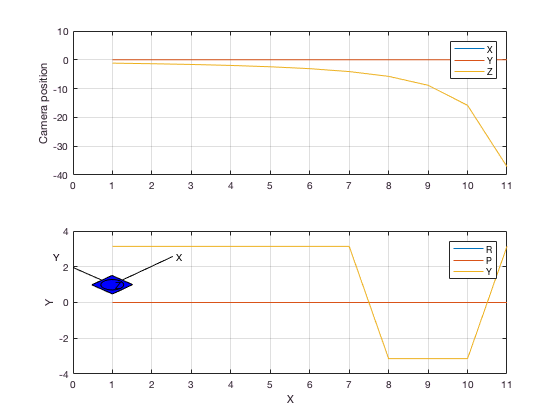

ibvs.plot_camera

## 15.3  Using other image featueres

## 15.3.1  Line features

P = circle([0 0 3], 0.5, 'n', 3);

ibvs = IBVS_l(cam, 'example');

----------------------------
canned example, line-based IBVS with three lines
----------------------------


ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

ans =    -2.6180    1.5708   -0.5236
    0.0125    0.0125    0.0125

completed on error tolerance


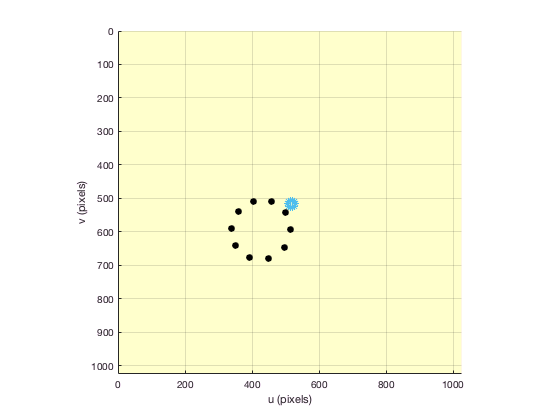

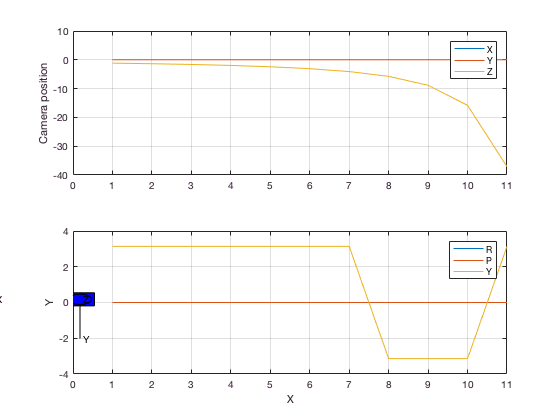

ibvs.run()

## 15.3.2  Circle features

P = circle([0 0 3], 0.5, 'n', 10);

Tc = SE3; %DIFF
p = cam.project(P, 'pose', Tc);

pn = cam.normalized(p)

pn =     0.1667    0.1348    0.0515   -0.0515   -0.1348   -0.1667   -0.1348   -0.0515    0.0515    0.1348
         0    0.0980    0.1585    0.1585    0.0980         0   -0.0980   -0.1585   -0.1585   -0.0980

x = pn(1,:); y = pn(2,:);
a = [y.^2; -2*x.*y; 2*x; 2*y; ones(1,numcols(x))]';
b = -(x.^2)';
E = a\b;

plane = [0 0 1 -3]; %DIFF
J = cam.visjac_e(E, plane)

J =          0         0         0   -0.0000   -0.0000   -0.0000
         0         0         0    0.0000   -0.0000   -0.0000
    0.1667    0.0000   -0.0000   -0.0000    1.0278   -0.0000
    0.0000    0.1667   -0.0000   -1.0278    0.0000    0.0000
   -0.0000   -0.0000   -0.0093    0.0000   -0.0000    0.0000


ibvs = IBVS_e(cam, 'example');

---------------------------------------------------
canned example, ellipse-based IBVS with 10 points
---------------------------------------------------


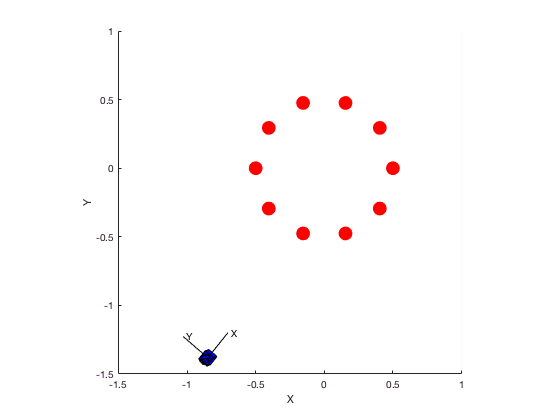

Error using svd
Input to SVD must not contain NaN or Inf.
Error in pinv (line 18)
[U,S,V] = svd(A,'econ');
Error in IBVS_e/step (line 196)
            v = -vs.lambda * pinv(J) * e;
Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('VisualServo/run', '/Users/corkep/rvc/vision/examples/VisualServo.m', 122)" style="font-weight:b

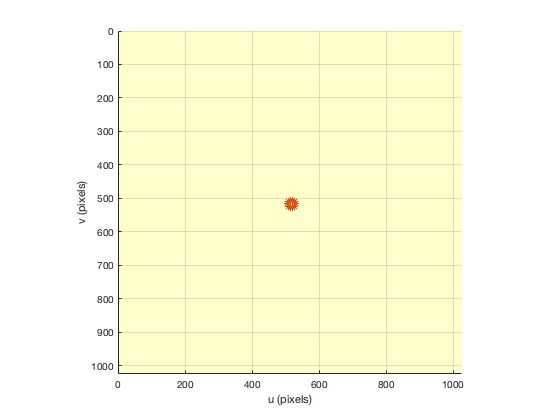

clf % DIFF
ibvs.run()

bdclose('all')